# **Digital Communications TTT4130 - Matlab Lab Sessions**

**Lab Responsible**: Johan Suarez (johan.suarez@ntnu.no)

`Prerequisites`

Up-to-date installation of `MATLAB `and `SIMULINK `including `Communications Toolbox. (NTNU students receive Campus license)`

`Instructions`

**All lab sessions are group projects. Groups will be assigned randomly and consist of 2-3 people.** 

This is a Matlab live script. The script will guide through the lab session with coding tasks accompanied by explanations and comments. The live script and the project report must be completed and delivered by **18.10.2024**

**Please download and install MATLAB/Simulink and include the Communications toolbox as add-in. **

**You are free to use any resource you think is useful. Collaboration and discussion between groups is encouraged. **

# `Project 2`

This lab session covers mainly *synchronisation *in digital communication systems.

### `Digital Communiction System Schematic`

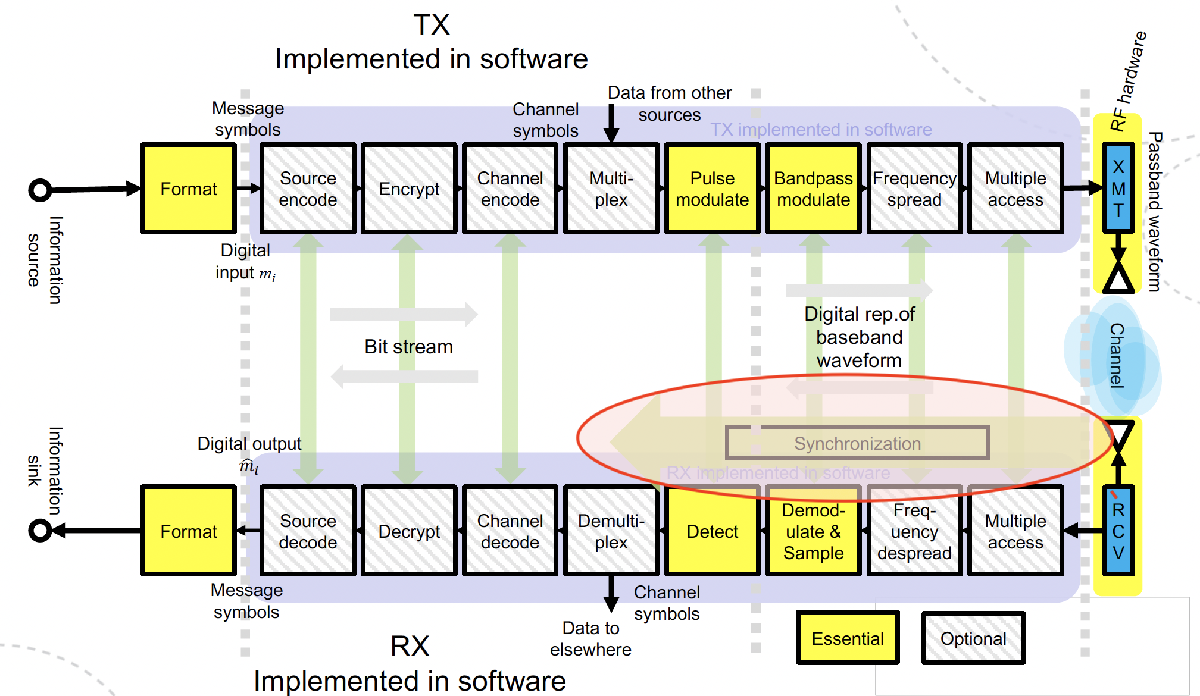

Specifically, the lab session covers the highlighted (red) parts of the schematic depicted above. 

`Course Content`

- Synchronisation in digital communication systems

- Why synchronisation is needed ... 

- Channel and hardware effects 

#### `System Configuration (known from Project 1)`

% Symbol Rate 
symRate = 1000;         % 1/s



SNR = Simulink.Parameter(30)       % Signal to Noise ratio, specifically Energy per bit to Noise Power density ratio (Eb/No)

SNR =   Parameter with properties:

          Value: 30
     Complexity: 'real'
     Dimensions: [1 1]
      CoderInfo: [1×1 Simulink.CoderInfo]
    Description: ''
       DataType: 'auto'
            Min: []
            Max: []
           Unit: ''


Select modulation scheme

modScheme = "BPSK"

modScheme = "BPSK"




% For M-ary QAM specify modulation order (TODO: assert modOrder == 2/4 for modScheme == BPSK/QPSK)

modOrder = 2

modOrder = 2

Specify Transmit Filter Parameters

alpha =0.35  % Nyquist Filter Roll-Off Factor

alpha = 0.3500



filterLenSymbols = 10;            % Filter Length in Symbols


samplesPerSymbol = 8;             % Filter Upsampling Factor


################################# NEW  ##################################

% Specify the "virtual" carrier frequency 

fCRes = Simulink.Parameter(0);


% Phase Offset

phaseOffsets = Simulink.Parameter([0;pi/8;pi/4;pi/2;pi]);

phaseOffsetSelector  = Simulink.Parameter(1);


% Toggle Synchronisation Processes

toggleFLL = Simulink.Parameter(1); 

toggleTimingRecovery = Simulink.Parameter(1); 

togglePLL = Simulink.Parameter(1); 


% True phase and frequency offset value

phaseOffsetSelector.Value = 2;

fCRes.Value = 15;

disp("Phase offset (rad): "+num2str(phaseOffsets.Value(phaseOffsetSelector.Value)))

Phase offset (rad): 0.3927



disp("Freq offset (Hz): "+num2str(fCRes.Value))

Freq offset (Hz): 15


`Task1 : Channel Effects`

**TODO: Provide more detail regarding the phase and frequency impairment model. **

Investigate which effects a phase offset ($\Delta \phi_{\textrm{LO}}$) and a frequency offset ($\Delta f_{LO}$ ) between the Tx and Rx local oscillator (LO) have on the received signal. Use the signal model for an analytic signal upconverted to passband

##                                 
$$s_+(t) = s(t) e^{j2\pi f_{c,tx}t}$$


which is mixed to baseband by a receiver LO with frequency $f_{c,Rx}=f_{c,Tx}+\Delta f$ and relative phase offset $\Delta \phi_{\textrm{LO}}$. In this task assume that $s(t)$ are downsampled complex symbols.

Considering the frequency and phase offset, then the received signal can be rewritten as:

## 
$$s_+(t) = s(t) e^{j2\pi ((f_{c,rx}+\Delta f)t+\Delta \phi)} = s(t) e^{j2\pi t f_{c,rx}}e^{j2\pi t \Delta f}e^{j2\pi \Delta \phi}$$


We will use this expression to generate a signal with phase and frequency impairments in Matlab.

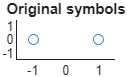

% Time of Frame including barker code (barker code is technically only needed for last exercise)
time = (0:1/symRate:1-1/symRate+1/symRate * 13)'; 

% Generate Tx message symbols
Nmsg = 200;
bitsI = randi([0 1], Nmsg, 1);
barker_code = [-1 -1 -1 -1 -1 +1 +1 -1 -1 +1 -1 +1 -1];
symTx_msg = 2*bitsI - 1;
symTx = [barker_code';symTx_msg];

% Plot Tx symbols
figure;
scatter(symTx,zeros(1,length(symTx)))
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
title("Original symbols")

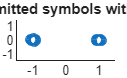


% Generate real and imaginary parts of the noise
Noise_R = randn(length(symTx),1);
Noise_I = randn(length(symTx),1);
% By default, randn considers mean 0 and variance 1 (unitary energy per symbol)

% Combine them to create complex Gaussian noise
Noise_C = 1/sqrt(2)*(Noise_R + Noise_I*1j);
% Real and Imaginary noise have energy per symbol equal to 1
% We divide by sqrt(2) to obtain unit energy in the Complex Noise

% Impair Tx signal with noise
symTx = symTx + (1/SNR.Value)*Noise_C;
% Since fc_Tx takes values in -1 and 1, its energy per symbol is 1
% Since both symTx and Noise_C have the same length and energy per symbol, they have the same energy.
% We divide Noise_C by the SNR value, so that the Signal to Noise ratio is satisfied

% Plot Tx symbols with noise
figure;
scatter(real(symTx),imag(symTx))
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
title("Transmitted symbols with noise")

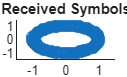


% Upconversion
symTx_upconv = zeros(length(symTx)*samplesPerSymbol,1);
for i=0:length(symTx)-1
    symTx_upconv(i*samplesPerSymbol+1) = symTx(i+1);
end

% Implement phase and frequency impairments
Fs = symRate * samplesPerSymbol; % sampling frequency
time2 = (0:length(symTx_upconv)-1)'/Fs;
symRx = exp(1j*phaseOffsets.Value(phaseOffsetSelector.Value)) *symTx_upconv .* exp(1j*2*pi*fCRes.Value.*time2);

% Downconvert signal to baseband
sigDC = zeros(length(symTx_upconv)/samplesPerSymbol,1);
for i=0:length(symRx)/samplesPerSymbol-1
    sigDC(i+1) = symRx(i*samplesPerSymbol+1);
end

% Plot received symbols, after carrier frequency offset
figure;
scatter(real(sigDC), imag(sigDC))
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
title("Received Symbols");

`Task 2 : Synchronisation Effects`

Synchronisation in (digital) communication systems aims for removing the phase and frequency effects and impairments discussed above. The simulink model contains blocks on the receiver end of the communication link that implement the following crucial synchronisation steps:

- Coarse Frequency Correction with e.g., **Frequency-Locked Loop (FLL) **(Matlab uses corrrelation and FFT based methodss)

- Timing Offset Correction with a **Symbol Synchronizer **

- Residual Frequency Offset Correction and Phase Sychronisation with a **Phase-Locked Loop (FLL)**

**Toggle the different synchronisation steps and observe the resulting signal characterisitcs (eye diagram, constellation diagram, signal spectrum) in each case. Explain the observations and argue mathematically where you see fit. **

When simulating with no carrier frequency impairments:

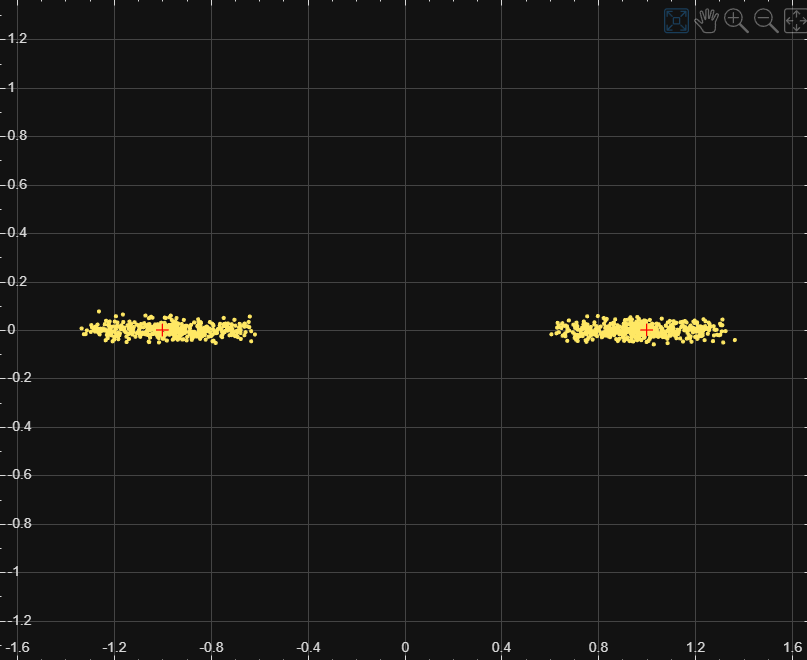     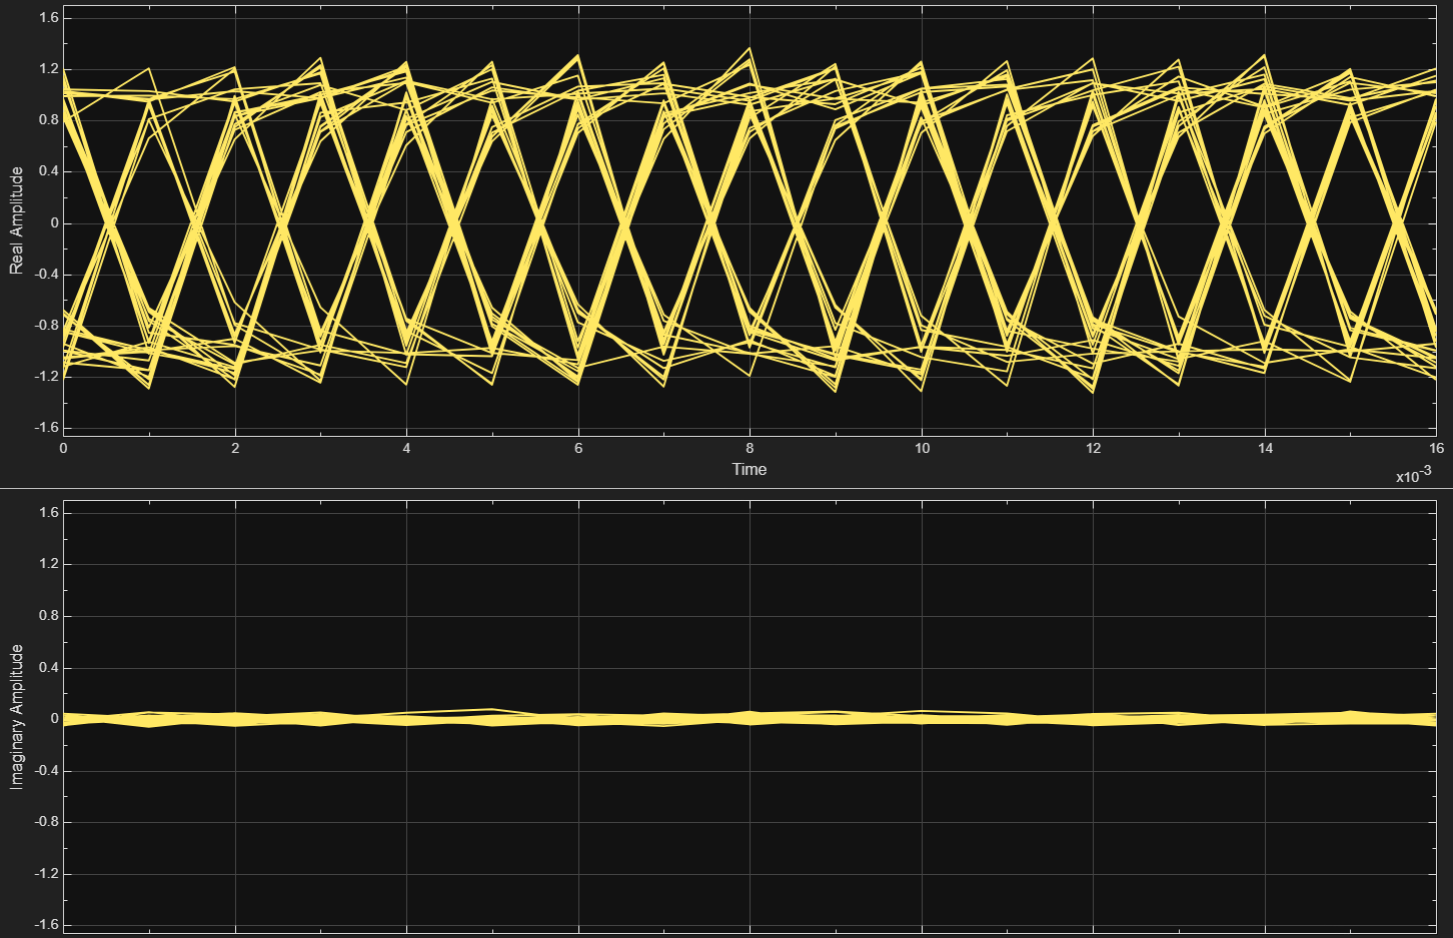

Activating the Symbol Sunchronizer  stabilizes the eye diagram visualization and constellation diagram:

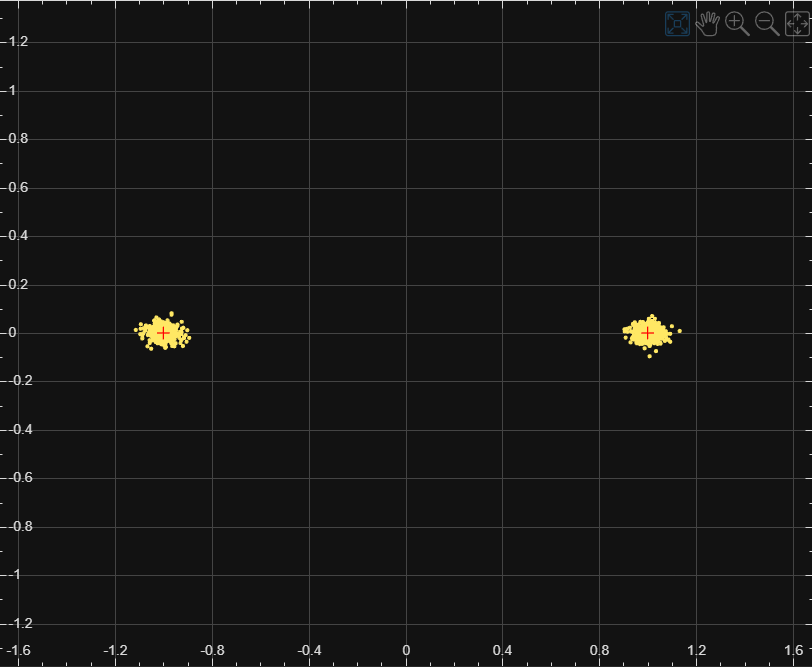     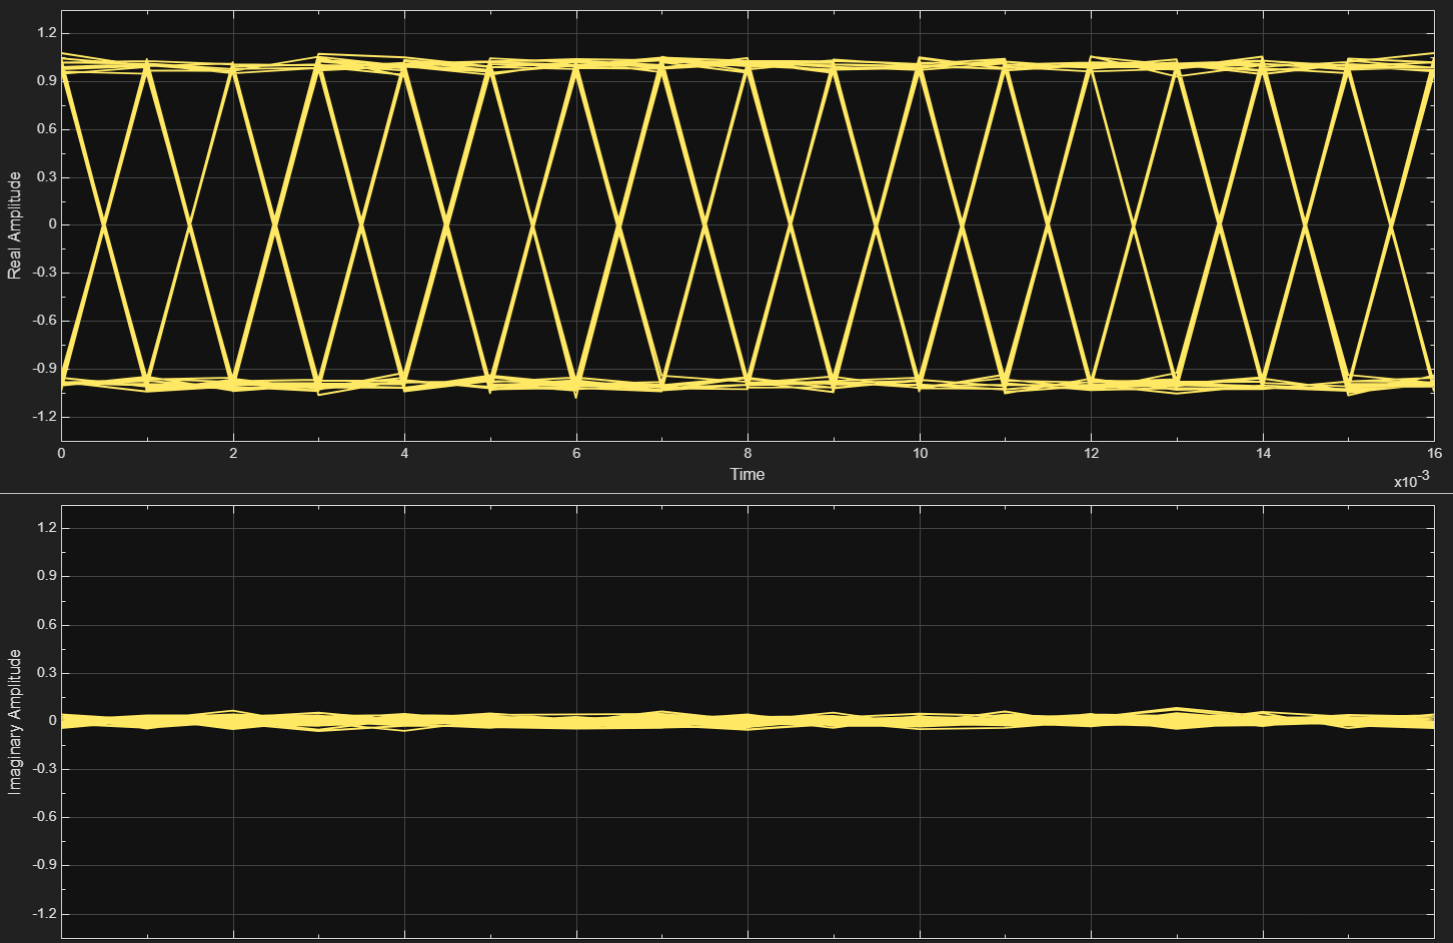

Now, introducing only a phase offset, the constelation diagram rotates. The eye diagram shows that the signals have both a real and imaginary component.

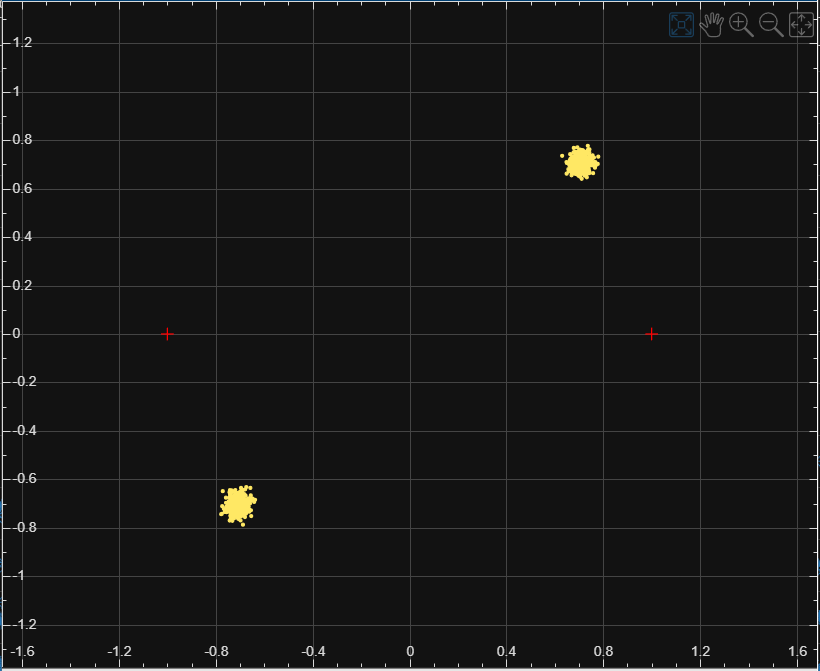     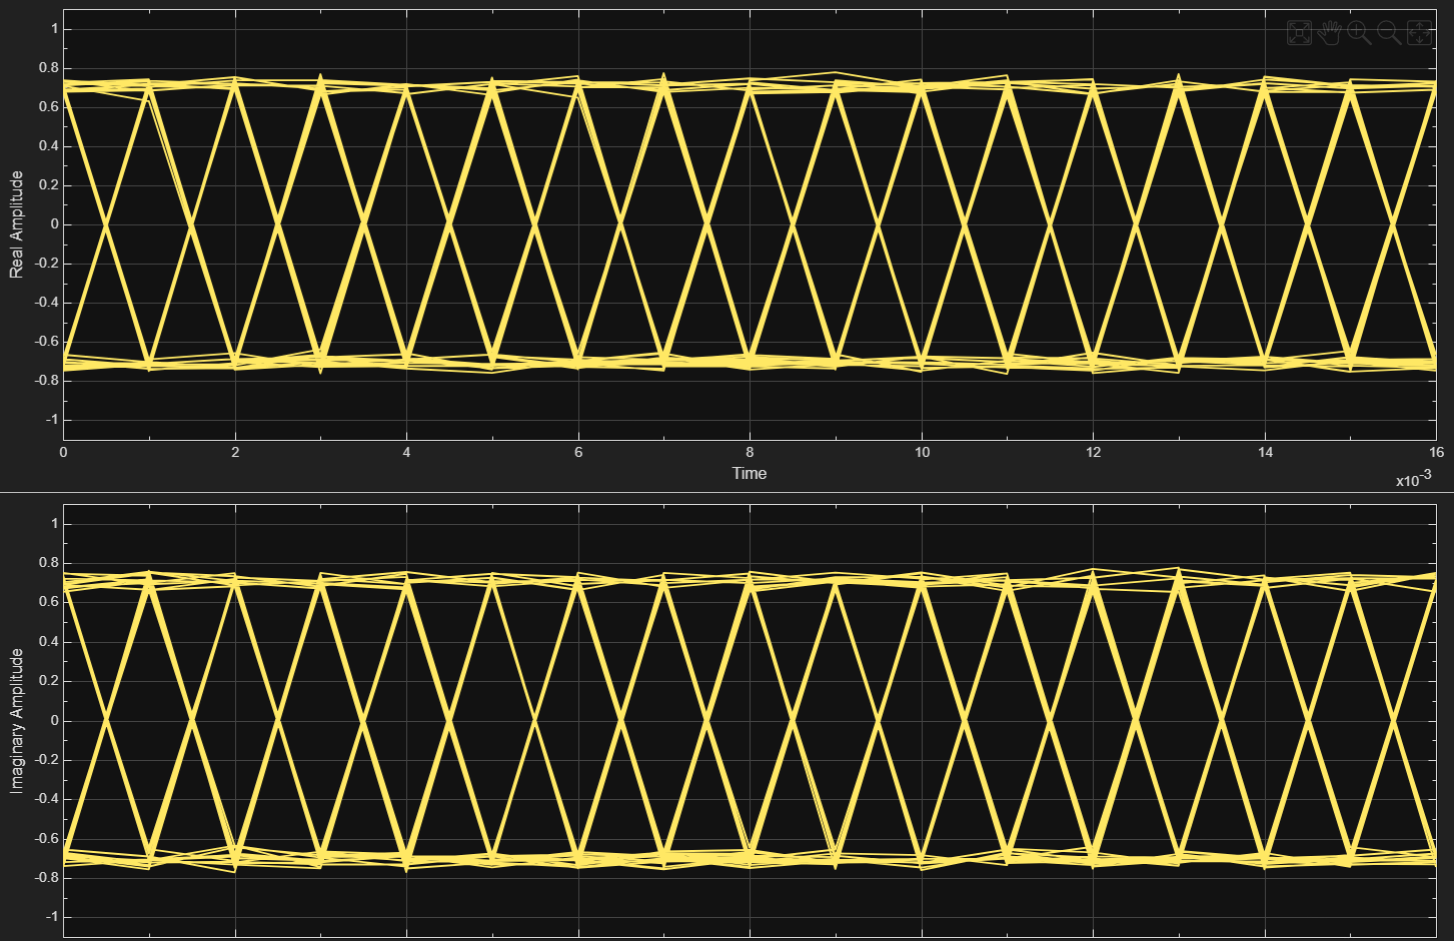

Now, if in addition there is also a frequency offset, the constellation diagram rotates in time. Since the signal mantains its amplitude, but rotates in the complex plane, the eye diagram present varying amplitudes in the real and imaginary time domain.

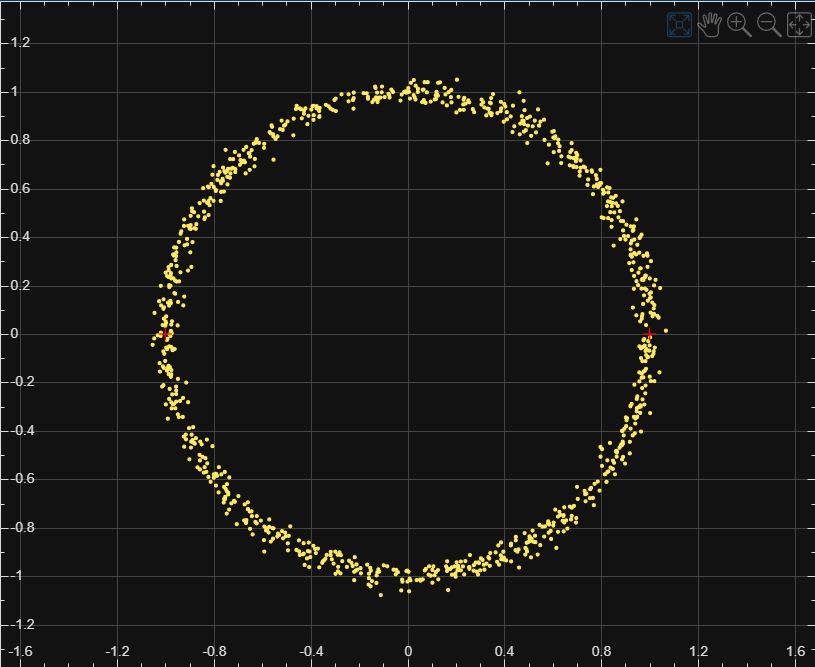     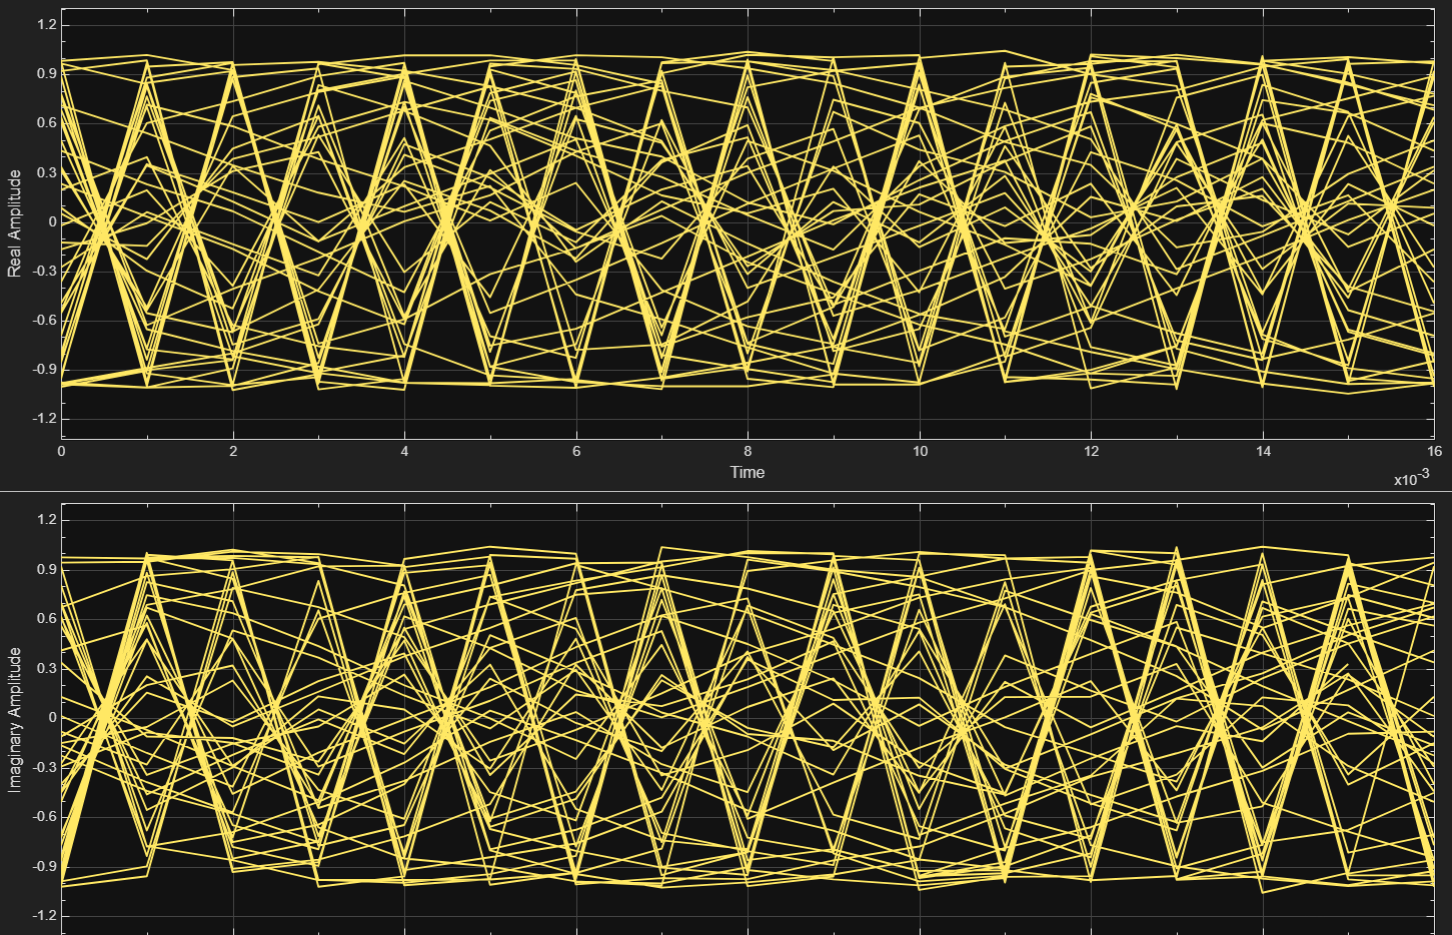

This ocurrs because carrier frequency offset rotates the data. This can be described mathematically as follows:


$$s_+(t) = s(t) e^{j2\pi ((f_{c,rx}+\Delta f)t+\Delta \phi)} = s(t) e^{j2\pi t f_{c,rx}}e^{j2\pi t \Delta f}e^{j2\pi \Delta \phi}$$


When activating Frequency_Locked_Loop, without Phase_Locked_Loop, this rotation is compensated, but mantains a constant phase offset:

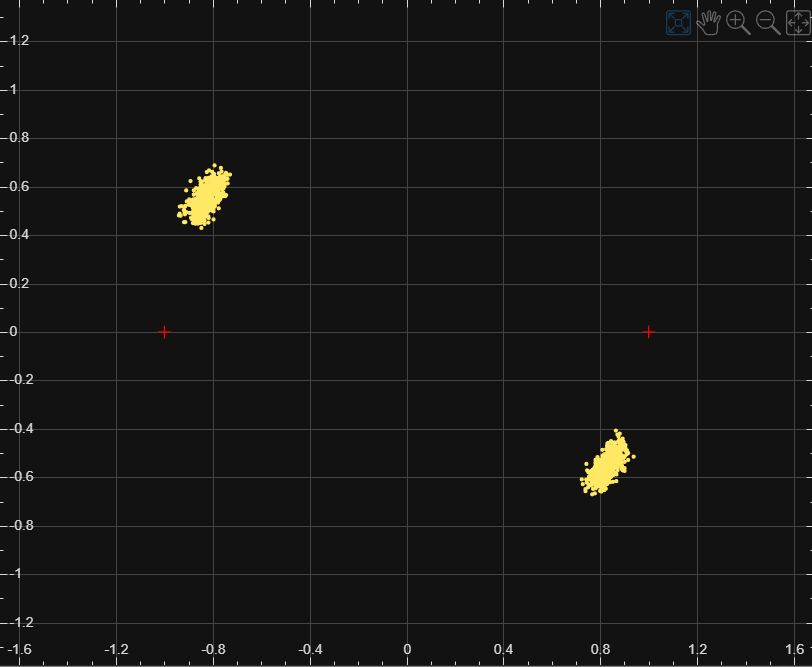     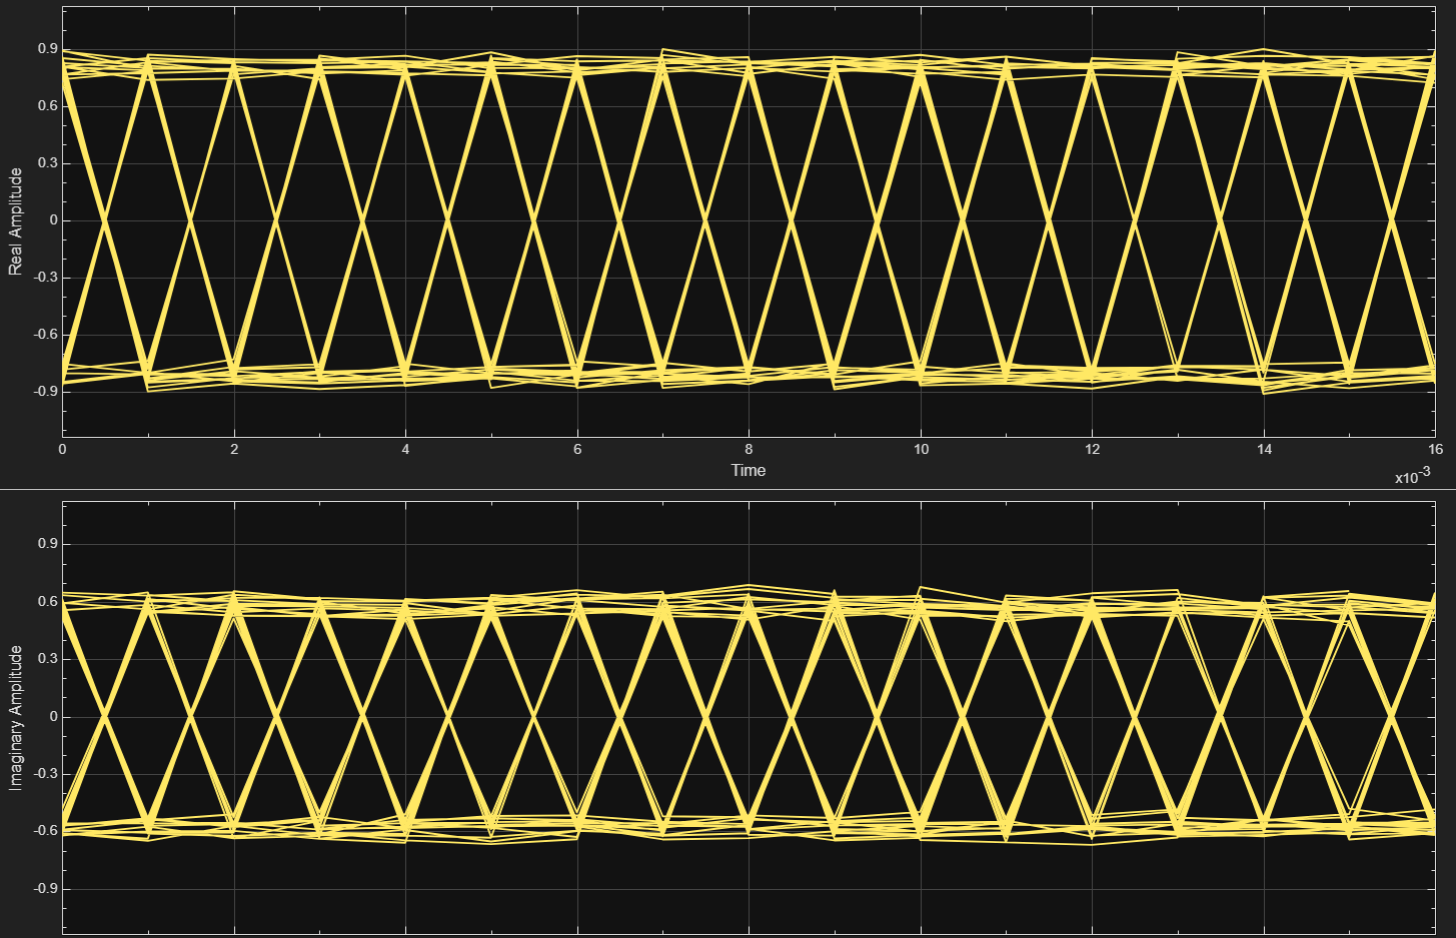

Now, activating the Phase_Locked_Loop compensates for frequency offset, succesfully recovering the original symbols:

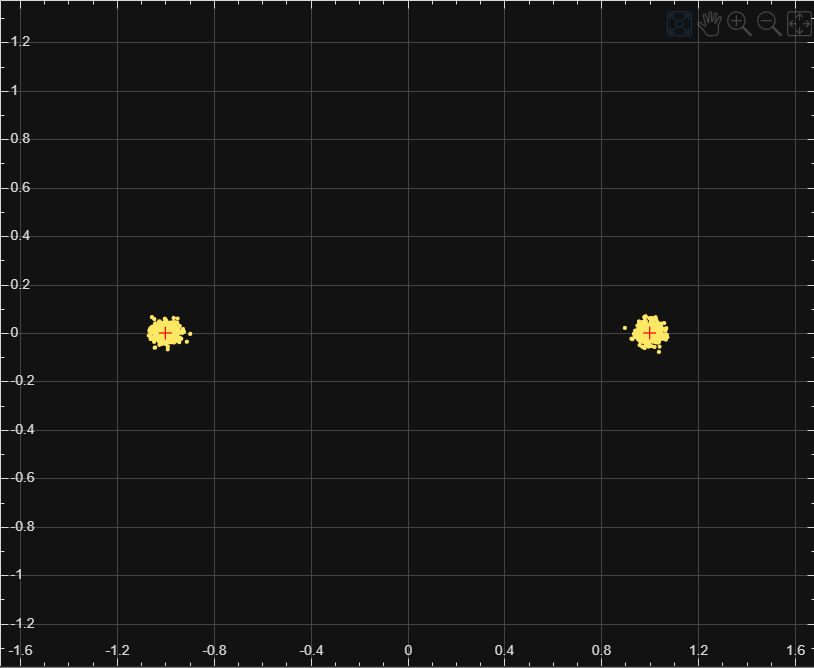    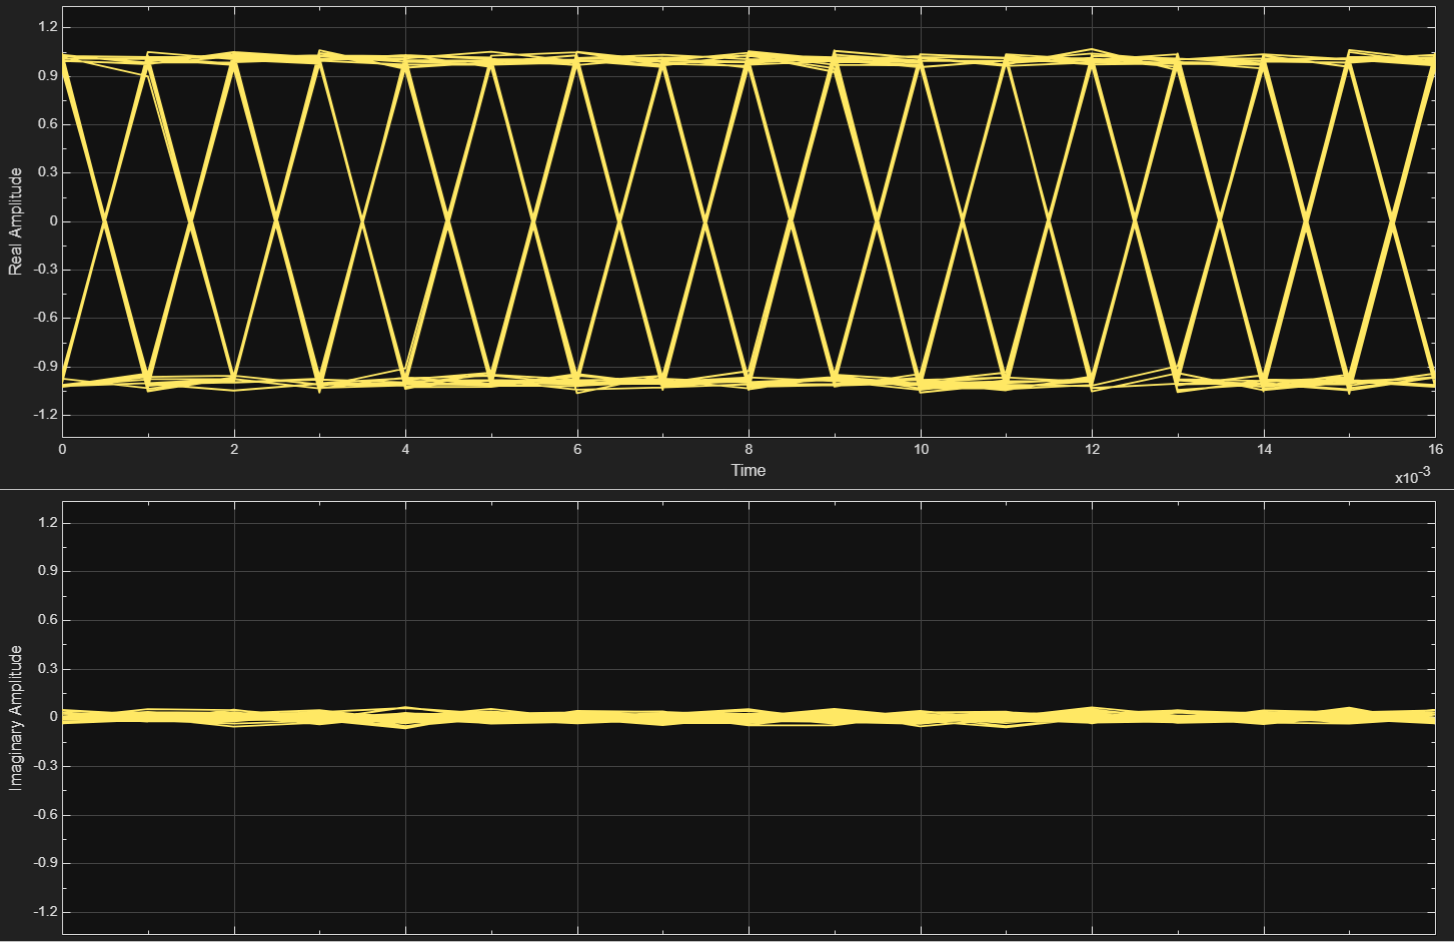

`Task 3 : Implementation of a Costas-Loop (data-free synchronization)`

 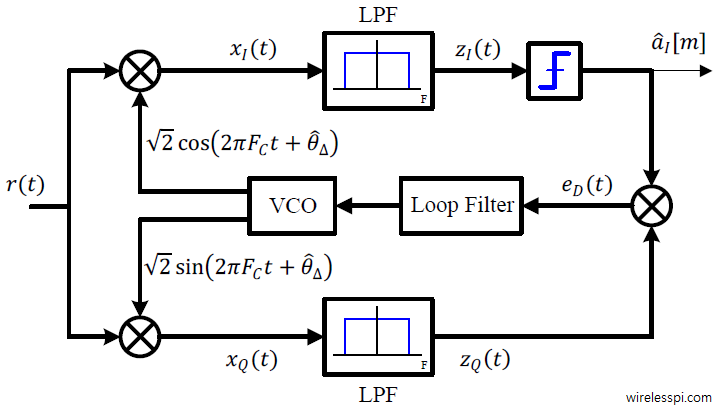

The illustration above shows the principle architecture of a *Costas Loop* for a **BPSK** receiver architecture (**NB! The illustration above treats a passband signal; our system operates on a *****complex baseband  signal***). The Costas loop is a variation of the traditional PLL that uses the IQ demodulation principles to lock onto the phase (and frequency) of a signal. 

The first step in the processing chain is the generation of the error signal $e_D$ which measures the phase difference between the reference sinusoid and the input signal. 

The *loop filter *is an integral part of the PLL. The design of the loop filter largely determines the performance characteristics of the PLL. The loop filter follows the basic structure

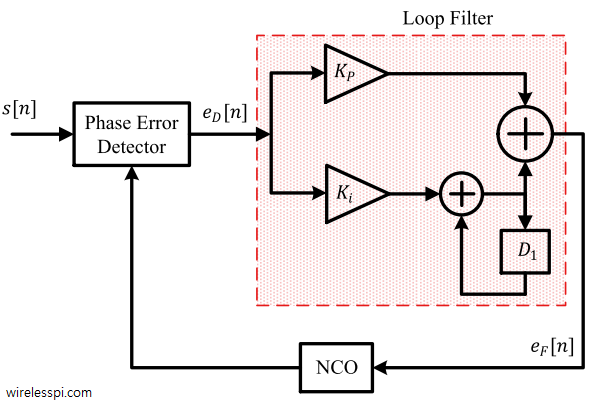

with appropriate filter coefficients $K_p
$ and $K_i$. (The *D1 *block is a one-step time-delay)

The generated and loop filtered *error signal *$e_F$ serves as input to a *Numerically Controlled Cscillator* (NCO).The NCO adjusts the phase of the generated sinusoid as

                                                             
$$\phi_{NCO}\leftarrow\phi_{NCO}+K_0e_F$$


where $K_0$ is the gain of the NCO. This essentially constitutes an integration or accumulation. 

Imlement the Costas Loop and enable your function in the simulink dashboard. Test the Costas Loop implementation first with the test signal you generated in *Task 1*. You can use the loop parameters defined in the function body. You are welcome to experiment with different parameter values; the loop parameter largely determine the the Costas loop performance, so it is interesting to observe how changes in parameters impact the outcome. 

**NB! Make sure that *****modScheme = "BPSK" *****when testing the function in the Simulink model. **

% MATLAB Function

function symOut = costasLoop(symIn)

sigDC_costas =   -0.9083 - 0.3652i  -0.9088 - 0.3480i  -0.9174 - 0.3513i  -0.9432 - 0.2591i  -0.9903 - 0.0533i   1.0422 - 0.0315i   0.9869 - 0.1919i  -0.9873 + 0.1841i  -0.9854 + 0.2588i   0.9887 - 0.2287i  -1.0004 + 0.1578i   0.9899 - 0.0968i  -0.9948 + 0.0412i   0.9886 + 0.0426i   1.0115 + 0.1116i   1.0131 + 0.0945i   1.0425 + 0.1704i  -0.9839 - 0.1160i   1.0383 + 0.1175i  -0.9396 - 0.0469i  -0.9702 - 0.0032i  -0.9791 + 0.0387i  -1.0317 + 0.0346i   0.9912 - 0.0645i   0.9988 - 0.0867i  -1.0161 + 0.0959i   1.0359 - 0.0214i   1.0058 - 0.0614i  -0.9868 - 0.0020i  -0.9723 + 0.0251i   0.9924 + 0.0715i  -1.0044 + 0.0022i  -0.9681 - 0.0599i   0.9876 + 0.0549i  -0.9560 + 0.0036i  -1.0017 - 0.0431i  -0.9977 + 0.0271i  -1.0174 + 0.0004i  -1.0170 - 0.0354i  -1.0111 - 0.0308i   1.0175 - 0.0904i  -1.0071 + 0.0392i   0.9857 + 0.0151i   1.0096 - 0.0075i   0.9903 + 0.0126i   1.0002 - 0.0326i  -0.9630 - 0.0145i  -1.0052 - 0.0190i   1.0484 - 0.0091i   1.0312 + 0.0534i


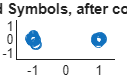

    
    symOut = zeros(1,length(symIn));

    % Loop Filter
    Kp = 0.1;
    Ki = 0.1;
    e1 = 0;

    e2 = 0;
    integrator = 0;
    NCO_phase = 0;

    % NCO Gain
    Ko = 1.5;

    % Implement Costas Loop
    for i = 1:length(symIn)

        % signal generated by VCO
        symOut(i) = symIn(i) * exp(-1j*NCO_phase);

        % Phase difference indicator, update e1
        e1 = imag(symOut(i)) * sign(real(symOut(i)));
        % This works, because e1 -> 0, when imag(symOut(i)) -> 0

        % Loop filter
        integrator = integrator + Ki*e1;
        e2 = Kp*e1+integrator;

        % symOut is the output of the NCO
        NCO_phase = NCO_phase + Ko*e2;

    end

end


% SIMULINK Function
% This function was copied directly into MATLAB Function block in Simulink

function symOut = iCostasLoop(symIn)

    % warning() function was used to receive information in Diagnostic Viewer
    warning("Custom Costas Loop Function is running...")
    
    symOut = complex(zeros(length(symIn),1));
    
    % Loop Filter
    Kp = 0.1;
    Ki = 0.1;
    e1 = 0;
    e2 = 0;
    integrator = 0;
    NCO_phase = 0;
    
    % NCO Gain
    Ko = 1.5;
    
    % Implement Costas Loop
    for i = 1:length(symIn)
    
        % signal generated by VCO
        symOut(i) = symIn(i) * exp(-1j*NCO_phase);
    
        % Phase difference, update e1
        e1 = imag(symOut(i)) * sign(real(symOut(i)));
    
        % Loop filter
        integrator = integrator + Ki*e1;
        e2 = Kp*e1+integrator;
    
        % symOut is the output of the NCO
        NCO_phase = NCO_phase + Ko*e2;
    
    end
end


% MATLAB Function tested on impaired signal generated on Task 1

sigDC_costas = costasLoop(sigDC)

% Plot received symbols
figure;
scatter(real(sigDC_costas), imag(sigDC_costas))
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
title("Received Symbols, after costas loop");


`Task 4 : Data-aided synchronization`

We can make use of the *known *frame synchronisation sequence (preamble) to estimate the phase and frequency offset in the received symbols. Implement a function that estimates $\Delta\phi_{LO} $ and $\Delta f_{LO}$ from the recieved input signal. Use the estimated values to synchronize the received symbols. 

**NB! If you want to try integrating data-aided synchronisation into the Simulink model, note that the known Barker code preamble has an offset of ****10 samples ****from the start of the input sequence *****symIn*****. For application in the Simulink model, the CFO estimation needs to account for noise in the CFO estimation across frames. For this purpose the following code snippet is included in the function below**

*Can you explain this?*

phase =     0.3823
    0.4752
    0.6344
    0.7492
    0.7723
    0.9028
    0.9381
    1.0900
    1.1353
    1.2327
    1.3415
    1.4254
    1.5011


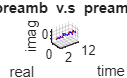

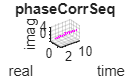

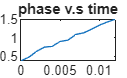

phi0 = 0.3823

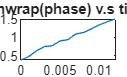

ans =    14.7937   25.3343   18.2641    3.6795   20.7747    5.6153   24.1817    7.2072   15.4954   17.3221   13.3549   12.0401


freq_offset = 14.8386

% MATLAB Function

function syncdSymOut = dataAidedSync(symIn, symRate)

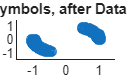


    % Known premable
    preamble = [-1 -1 -1 -1 -1 +1 +1 -1 -1 +1 -1 +1 -1].';
    
    % Obtain phase change from the complex preamble
    r_preamb = symIn(1:length(preamble));
    phaseCorrSeq = r_preamb .* conj(preamble);

    phase = angle(phaseCorrSeq)
    
    % Plot: 3D complex preamble vs original preamble 
    figure
    hold on;
    axis equal;
    grid on;
    xlabel('time'); ylabel('real'); zlabel('imag');
    for i = 1:length(r_preamb)
        quiver3(i,0,0,0,real(r_preamb(i)),imag(r_preamb(i)),0,'Color', [0 0 1]);
        quiver3(i,0,0,0,real(preamble(i)),0,'Color', [1 0 0]);
    end
    view(3);
    title("r\_preamb v.s preamble");
    hold off;
    
    % Plot: Product of complex preamble with original preamble
    figure
    hold on;
    axis equal;
    grid on;
    xlabel('time'); ylabel('real'); zlabel('imag');
    for i = 1:length(r_preamb)
        quiver3(i,0,0,0,real(phaseCorrSeq(i)),imag(phaseCorrSeq(i)),0,'Color', [1 0 1]);
    end
    view(3);
    title("phaseCorrSeq");
    hold off;

    % Phase v.s time plot (before unwraping)
    figure
    plot((0:length(phase)-1)/symRate, phase)
    title("phase v.s time")

    % Recover phase offset
    phi0 = phase(1)

    % Unwrap phase
    phase = unwrap(phase);

    % Phase v.s time plot (after unwraping)
    figure
    plot((0:length(phase)-1)/symRate, phase)
    title("unwrap(phase) v.s time")

    % Aproximation for the slope of unwrap(phase)
    freq_offset_aprox = zeros(1,1);
    for i=1:(length(phase)-1)
        slope = (phase(i+1)-phase(i))*symRate/(2*pi);
        freq_offset_aprox = [freq_offset_aprox slope];
    end
    freq_offset_aprox(2:end)
    freq_offset = mean(freq_offset_aprox(2:end))
    
    % Rotate Data to compensate for phase and frequency offset
    time3 = (0:length(symIn)-1)'*1/symRate;
    syncdSymOut = exp(-1j*phi0) *symIn .* exp(-1j*2*pi*freq_offset.*time3);

end

% SIMULINK Function
% This function was copied directly into MATLAB Function block in Simulink

function symOut = iDataAidedSync(symIn)

    % Used warning() function to receive information in the Diagnostic Viewer
    warning("Custom Data Aided Sync Function is running...")
    
    % Known Symbol Rate
    symRate = 1000;
    
    % symOut instantiated
    symOut = zeros(size(symIn,1)-13-16, size(symIn,2)) * (0+0j);
    
    % CFO frequency estimate initializes as zero
    persistent cfo_est 
    alpha = 0.7;
    if isempty(cfo_est)
        cfo_est = 0;
    end
    
    % complex preamble is multiplied with barker code
    preamble = [-1 -1 -1 -1 -1 +1 +1 -1 -1 +1 -1 +1 -1].';
    r_preamb = symIn(11:length(preamble)+10);
    phaseCorrSeq = r_preamb .* conj(preamble);
    
    % Transform into phase, and compute phase offset
    phase = angle(phaseCorrSeq);
    phi0 = phase(1);
    phase = unwrap(phase);
    figure;
    plot(1:length(phase),phase);
    
    % Approximation of phase slope
    freq_offset_aprox = zeros(1,1);
    for i=1:(length(phase)-1)
        slope = (phase(i+1)-phase(i))*symRate/(2*pi);
        freq_offset_aprox = [freq_offset_aprox slope];
    end
    freq_offset_aprox(2:end);
    freq_offset = mean(freq_offset_aprox(2:end));
    
    % CFO estimate is updated, using previous estimate and new freq_offset
    cfo_est = freq_offset*alpha + (1-alpha)*cfo_est;
    
    % symIn symbols are rotated to compensate for carrier offsets
    symIn_slice = symIn(10+1:1:end);
    time3 = (0:length(symIn_slice)-1)'*1/symRate;
    symOutDummy = exp(-1j*phi0) * symIn_slice .* exp(-1j*2*pi*cfo_est.*time3);
    
    % Obatined estimates
    warning("Phase offset estimate:     "+num2str(phi0))
    warning("Frequency offset estimate: "+num2str(cfo_est))
    
    % Remove Padding (of length 16)
    symOut = symOutDummy(1:987-16);

end


% MATLAB function tested on signal from Task 1

sigDC_dataaided = dataAidedSync(sigDC, symRate);

% Plot received symbols
figure ; clf;
scatter(real(sigDC_dataaided), imag(sigDC_dataaided))
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
title("Received Symbols, after Data Aided Sync");